# Matrix Powers and the Dominant Eigenvector

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

This code sets up the activity.

A = [2 -1; 3/2 -1/2]

A =     2.0000   -1.0000
    1.5000   -0.5000


x = [1; -1]

x =      1
    -1


## Task 1

You can find one of the eigenvectors of a matrix *A* by repeatedly multiplying the matrix:

**v**≈*A*∗*A*∗*A*∗...∗*A*∗**x**

**v** is the *dominant* eigenvector, and **x** is any vector with the same number of rows as *A*.

The function `plotVector` was created for this course. It accepts one vector as input and adds it to the existing figure:

`plotVector``(``x``)`

plotVector(x)

## Task 2

Multiplying by *A* will result in a vector closer to the dominant eigenvector. Multiplying by *A* twice will be even closer.

plotVector(A*x)
plotVector(A*A*x)
legend("x", "A*x", "A*A*x", "Location", "northwest")

## Task 3

The more times you multiply by *A*, the closer the resulting vector will be to the dominant eigenvector. With each multiplication, you can see the vector's direction changing less and less.

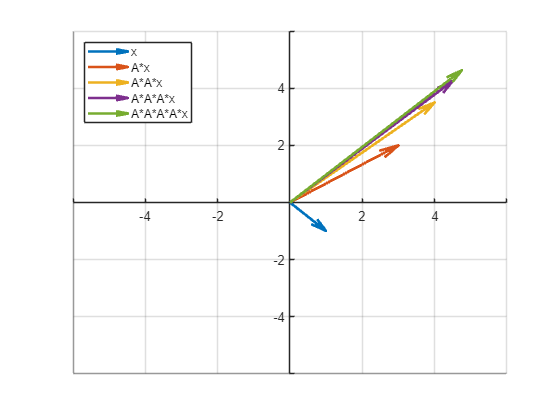

plotVector(A*A*A*x)
plotVector(A*A*A*A*x)
legend("x", "A*x", "A*A*x", "A*A*A*x", "A*A*A*A*x", "Location", "northwest")

function plotVector(vec)
    % Plot the vector vec
    hold on
    quiver(0,0,vec(1),vec(2),'-','MaxHeadSize',2/norm(vec),'AutoScale','off');
    hold off
    % Center the axis origin
    a = gca;
    a.XAxisLocation = 'origin';
    a.YAxisLocation = 'origin';
    a.Children(1).LineWidth = 2;
    xlim([-6 6])
    ylim([-6 6])
    % Remove the box around the axis
    box(a,'off')
    %Add a grid
    grid on
end